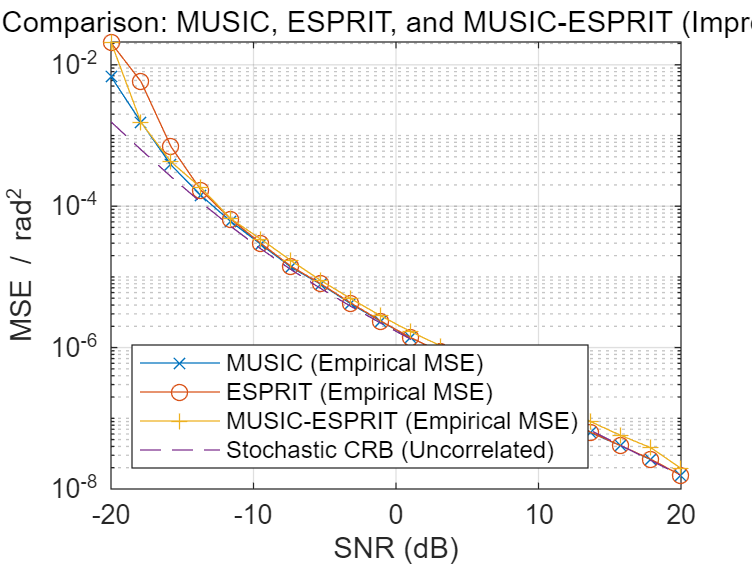

% Performance evaluation of ULA-based MUSIC, ESPRIT, and MUSIC-ESPRIT (Improved v2)
clear(); close all;

% Set up
wavelength = 1; % normalized
d = wavelength / 2;
n_elements = 10; % number of elements in ULA
design = design_array_1d('ula', n_elements, d);
doas = linspace(-pi/3, pi/3, 6); % 6 sources
power_source = 1;
snapshot_count = 1000; % Snapshots
source_count = length(doas);
grid_size = 2000; % spectrum resolution for MUSIC and MUSIC-ESPRIT

% Vary SNR from -20 dB to 20 dB
n_param_power_noise = 20;
param_power_noise = 10.^(-linspace(-20, 20, n_param_power_noise)/10);
n_repeat = 200;
mse_music = zeros(n_param_power_noise, 1);
mse_esprit = zeros(n_param_power_noise, 1);
mse_music_esprit = zeros(n_param_power_noise, 1);
crb = zeros(n_param_power_noise, 1);
snr = zeros(n_param_power_noise, 1);

for ii = 1:n_param_power_noise
    power_noise = param_power_noise(ii);
    snr(ii) = 10*log10(power_source / power_noise);
    
    % MUSIC
    cur_se_music = 0;
    valid_count_music = 0;
    
    % ESPRIT
    cur_se_esprit = 0;
    valid_count_esprit = 0;
    
    % MUSIC-ESPRIT
    cur_se_music_esprit = 0;
    valid_count_music_esprit = 0;
    
    for rr = 1:n_repeat
        % Generate snapshots
        [~, R, ~] = snapshot_gen_sto(design, doas, wavelength, snapshot_count, power_noise, power_source);
        
        % MUSIC
        sp_music = music_1d(R, source_count, design, wavelength, grid_size, ...
            'Unit', 'radian', 'RefineEstimates', true);
        if sp_music.resolved && ~isempty(sp_music.x_est) && length(sp_music.x_est) == source_count
            [~, idx] = sort(sp_music.x_est);
            sorted_x_est = sp_music.x_est(idx);
            [~, idx_doas] = sort(doas);
            sorted_doas = doas(idx_doas);
            cur_se_music = cur_se_music + sum((sorted_x_est - sorted_doas).^2);
            valid_count_music = valid_count_music + 1;
        end
        
        % ESPRIT
        k = 2 * pi * design.element_spacing / wavelength;
        sp_esprit = esprit_1d(R, source_count, k, 'Unit', 'radian', 'RowWeights', 'Default');
        if sp_esprit.resolved && ~isempty(sp_esprit.x_est) && length(sp_esprit.x_est) == source_count
            [~, idx] = sort(sp_esprit.x_est);
            sorted_x_est = sp_esprit.x_est(idx);
            [~, idx_doas] = sort(doas);
            sorted_doas = doas(idx_doas);
            cur_se_esprit = cur_se_esprit + sum((sorted_x_est' - sorted_doas).^2);
            valid_count_esprit = valid_count_esprit + 1;
        end
        
        % MUSIC-ESPRIT
        sp_music_esprit = music_esprit_1d(R, source_count, design, wavelength, grid_size, ...
            'Unit', 'radian', 'RefineRange', 0.1);
        if sp_music_esprit.resolved && ~isempty(sp_music_esprit.x_est)
            % Relax the condition: compute MSE for detected DOAs even if fewer than source_count
            num_detected = length(sp_music_esprit.x_est);
            if num_detected > 0
                [~, idx] = sort(sp_music_esprit.x_est);
                sorted_x_est = sp_music_esprit.x_est(idx);
                [~, idx_doas] = sort(doas);
                sorted_doas = doas(idx_doas);
                % Compute MSE for the detected DOAs (match the first num_detected DOAs)
                cur_se_music_esprit = cur_se_music_esprit + sum((sorted_x_est - sorted_doas(1:num_detected)).^2);
                valid_count_music_esprit = valid_count_music_esprit + 1;
            end
        end
    end
    
    % Compute MSE for each method
    if valid_count_music > 0
        mse_music(ii) = cur_se_music / (source_count * valid_count_music);
    else
        mse_music(ii) = NaN;
    end
    
    if valid_count_esprit > 0
        mse_esprit(ii) = cur_se_esprit / (source_count * valid_count_esprit);
    else
        mse_esprit(ii) = NaN;
    end
    
    if valid_count_music_esprit > 0
        mse_music_esprit(ii) = cur_se_music_esprit / (source_count * valid_count_music_esprit);
    else
        mse_music_esprit(ii) = NaN;
    end
    
    % Compute CRB
    crb(ii) = mean(diag(crb_uc_sto_1d(design, wavelength, doas, power_source, power_noise, snapshot_count)));
end
fprintf('\n');

% --- Plot, remove NaNs ---
valid_idx_music = ~isnan(mse_music);
valid_idx_esprit = ~isnan(mse_esprit);
valid_idx_music_esprit = ~isnan(mse_music_esprit);

figure;
semilogy(snr(valid_idx_music), mse_music(valid_idx_music), '-x', ...
         snr(valid_idx_esprit), mse_esprit(valid_idx_esprit), '-o', ...
         snr(valid_idx_music_esprit), mse_music_esprit(valid_idx_music_esprit), '-+', ...
         snr, crb, '--');
xlabel('SNR (dB)');
ylabel('MSE / rad^2');
grid on;
legend('MUSIC (Empirical MSE)', 'ESPRIT (Empirical MSE)', 'MUSIC-ESPRIT (Empirical MSE)', ...
       'Stochastic CRB (Uncorrelated)', 'Location', 'southwest');
title('MSE Comparison: MUSIC, ESPRIT, and MUSIC-ESPRIT (Improved v2)');